# MAT188 - Topic Assignment 1

In Topic Assignment 1, we will use the knowledge learned from Lab 2 and 3 to solve two electrical circuit problems. We assume you have already done the prelab and exercises.

In Lab 2 you learned how to set-up and solve a system of linear equations and Lab 3 introduced nodal analysis and mesh analysis for electrical circuits. An electrical circuit is shown below with two voltage sources and six resistors with a total of three loops. The known electrical parameters are given in the code below the figure. 

        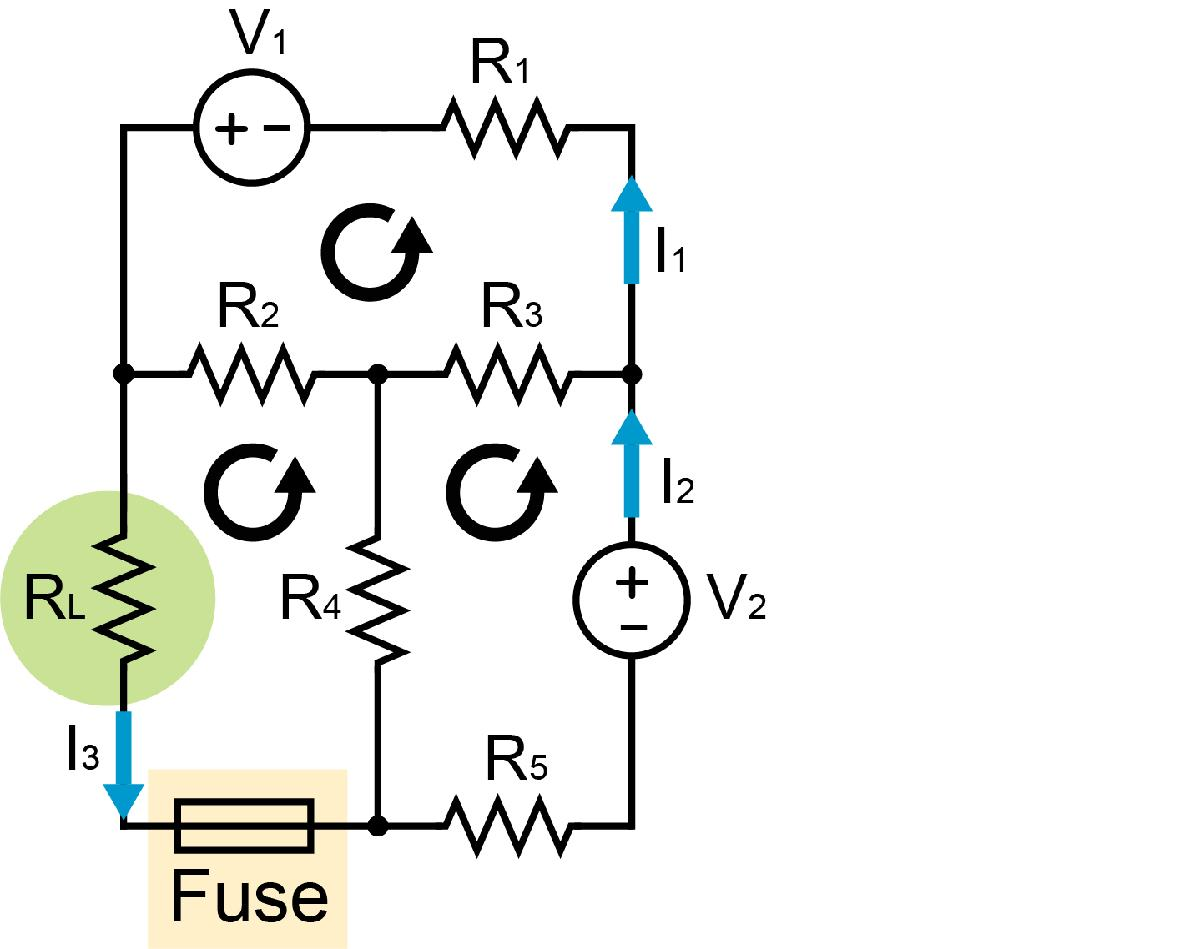    

### List of known electrical parameters

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%% Do not edit this section %%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Resistors
R1 = 8; R2 = 4; R3 = 4; R4 = 6; R5 = 1; % Ω

% Voltage sources
V1 = 120; V2 = 120; % V

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Question #1

A fuse can be included in an electrical circuit to prevent excessive current. When the current exceeds a rated value, the fuse will melt and break the electrical connection. A load resistance ($R_L$) is included in the circuit below. The goal of this problem is to determine the **minimum **$R_L$ required to prevent blowing the fuse. **The fuse in this circuit is rated for 5 amps.**

### **Using a numerical strategy**

Construct a system of equations to describe the circuit above, then write this system of equations in a matrix equation $A\;x=b$.

Hint 1: Use Kirchoff's current law to find the current over $R_2 ,R_3 ,R_4$ as a linear combination of $I_1 ,I_2 ,I_3$. Then substitute these into equations derived using Kirchoff's voltage law.

Hint 2: Include the unknown resistance as a variable in your system of equations.

            eg.  $x=\left\lbrack \begin{array}{c}
I_1 \\
I_2 \\
R_L 
\end{array}\right\rbrack$

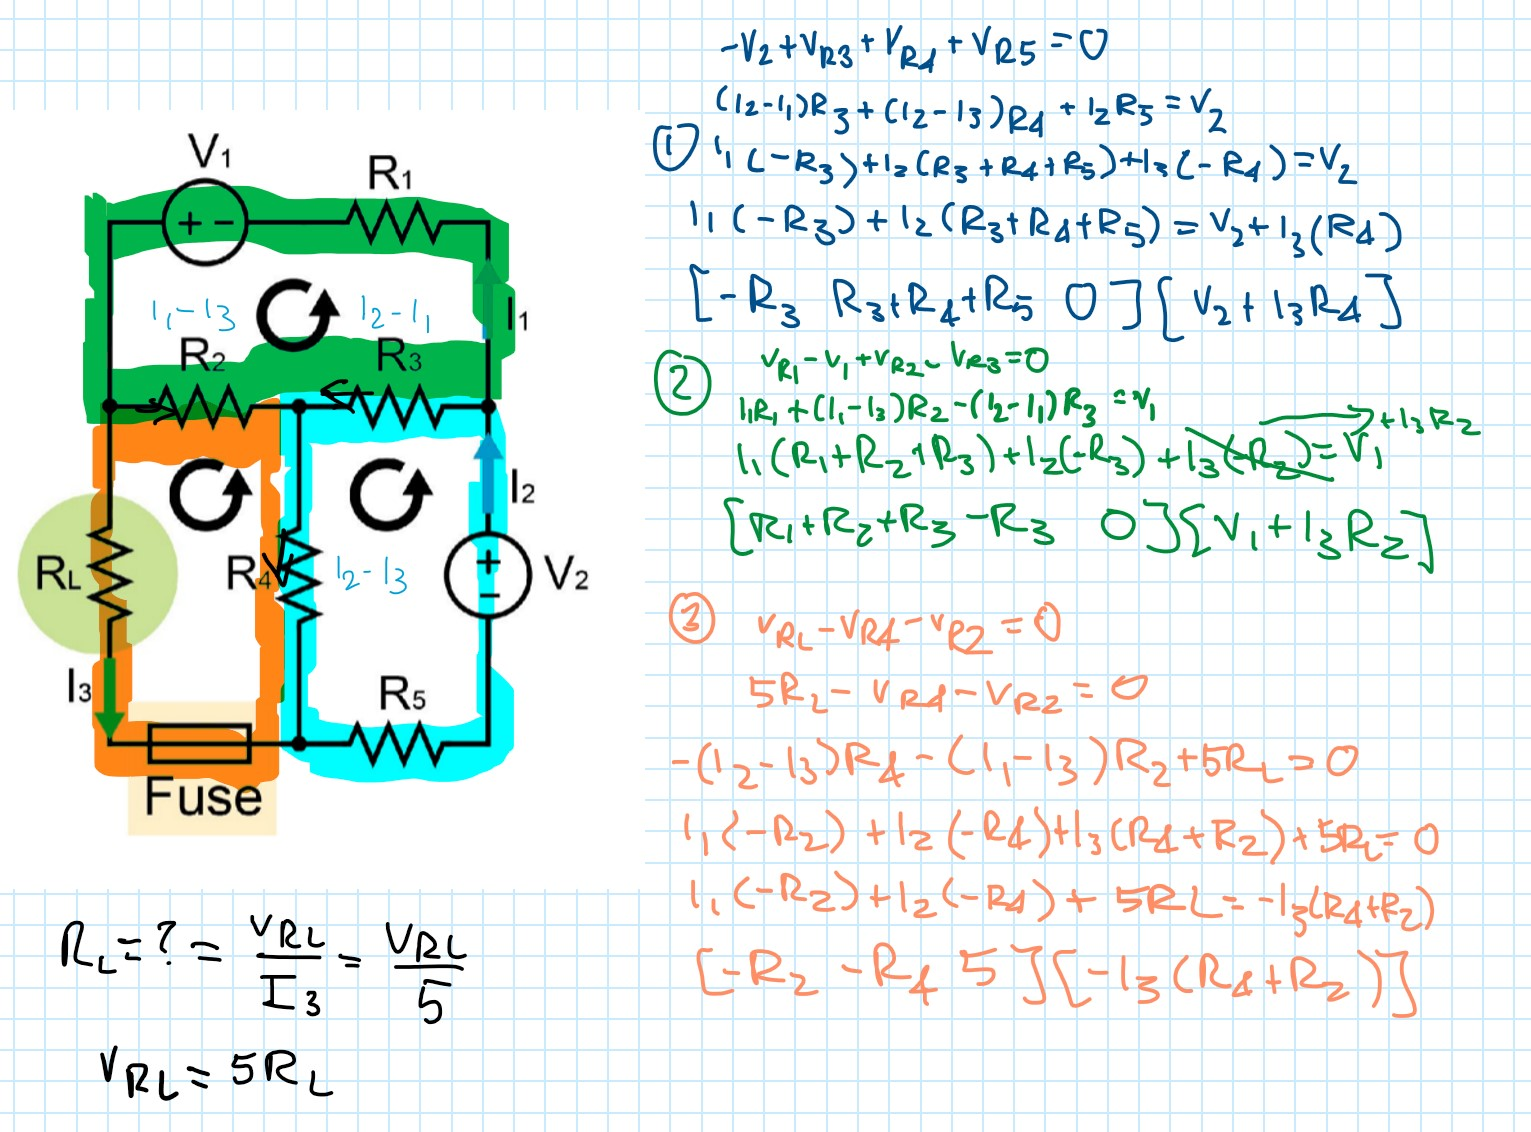

%%% complete the code below %%%
I3=5;
A = [ -R3 R3+R4+R5 0; R1+R2+R3 -R3 0; -R2 -R4 5]

A =     -4    11     0
    16    -4     0
    -4    -6     5


b = [ V2+I3*R4; V1+I3*R2; -I3*(R4+R2) ]

b =    150
   140
   -50


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Recall there are multiple ways to solve a system of linear equations in MATLAB. Use your choice of method (`rref`, `linsolve`, matrix division) to solve this system.

%%% enter your code below %%%
matrix = A\b

matrix =    13.3750
   18.5000
   22.9000


matrix(3)

ans = 22.9000

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Tell MATLAB to display the value for $R_L$. You should be getting this value directly from a variable in memory. 

**               Warning: **Do not manually enter in a number here.

final_answer = [ matrix(3) ];   %%% ← complete this line %%%
fprintf('The minimum R_L to prevent blowing the fuse is %.4f.', final_answer);

The minimum R_L to prevent blowing the fuse is 22.9000.

### Using a graphical strategy

Create a vector of hypothetical resistance values to substitute into the circuit.

This vector should range from **0 to 50 Ω, in steps of 0.5 Ω**.

RL_values_to_try = [ 0:0.5:50 ];   %%% ← complete/modify the following line %%%

Using a for-loop, iterate over this vector and **compute the corresponding current through the fuse**, given the hypothetical resistance values above. Store this into `I_fuse`.

I_fuse = zeros(length(RL_values_to_try), 1);   % pre-allocate the output vector

for kk = 1:length(RL_values_to_try)
    current_RL = RL_values_to_try(kk);
    
    %%% enter your code below %%%
    A = [ -R3 R3+R4+R5 0; R1+R2+R3 -R3 0; -R2 -R4 current_RL];
    b = [ V2+I3*R4; V1+I3*R2; -I3*(R4+R2) ];
    matrix = A\b;
    I_fuse(kk) = matrix(3);
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
end

I_fuse=I_fuse.'

I_fuse =        Inf  229.0000  114.5000   76.3333   57.2500   45.8000   38.1667   32.7143   28.6250   25.4444   22.9000   20.8182   19.0833   17.6154   16.3571   15.2667   14.3125   13.4706   12.7222   12.0526   11.4500   10.9048   10.4091    9.9565    9.5417    9.1600    8.8077    8.4815    8.1786    7.8966    7.6333    7.3871    7.1562    6.9394    6.7353    6.5429    6.3611    6.1892    6.0263    5.8718    5.7250    5.5854    5.4524    5.3256    5.2045    5.0889    4.9783    4.8723    4.7708    4.6735


**Plot** the resultant current through the fuse against the hypothetical resistance values.

- The fuse current and resistance value pairs should be a scatter plot

- Include a line indicating the maximum current of the fuse

- Remember to label your plot axes and add a plot title

Hint: The following commands may be useful.

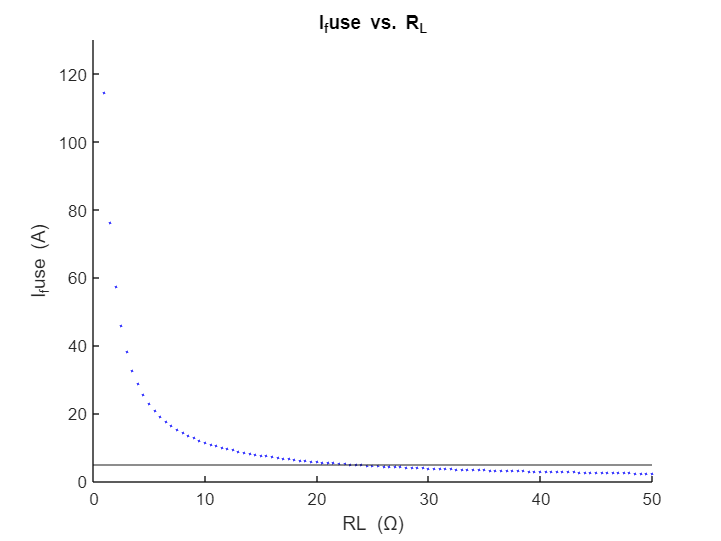

figure;  % initialize new figure

%%% enter your code below %%%
scatter(transpose(RL_values_to_try),I_fuse,1,'blue')
title('I_fuse vs. R_L')
xlabel('RL  (Ω)'), ylabel('I_fuse (A)')
xlim([0 50])
ylim([0 130])
yline(5)

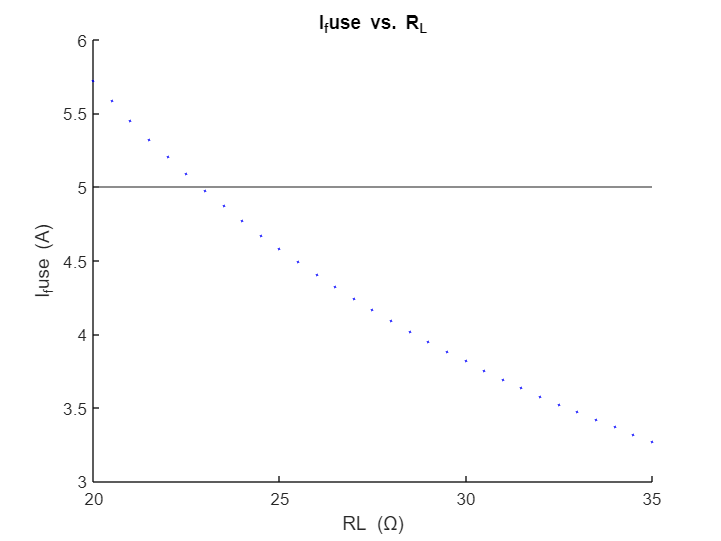

scatter(transpose(RL_values_to_try),I_fuse,1,'blue')
title('I_fuse vs. R_L')
xlabel('RL  (Ω)'), ylabel('I_fuse (A)')
xlim([20 35])
yline(5)

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### Final answer

Based on the graph, the minimum resistance $R_L$ required to prevent blowing the fuse is approximately **[ >>> 23 **Ω** <<< ]**.

## Question #2

**The old fuse has now been replaced with a 30 ampere fuse.**

Electric power is the rate of energy transfer by an electric circuit and is given in units of watts (joules per second). Often, it is desirable to determine a resistance that can allow the maximum transfer of power to a given load. Given the circuit above, **what value of **$R_L$** allows for maximum power dissipation?** Power can be calculated from the equation $P=I^2 R$.

### Short answer question

If we'd like to solve this system of equations for power (which includes a squared-term), which of the following methods/functions is preferred? 

Choose one and justify why in one sentence:  `rref`  |  `linsolve`  |  matrix division (`ldivide`)  |  matrix division (`rdivide`)  |  **none of the above / not solveable**

**Your answer:**     the system of equations created above is not solvable for power using the methods above because I3 is now an unknown variable and so we must manually rearrange entries in the matrix to solve for all the currents (unlike question 1 where we were searching for the minimum value of RL that caused the current of the fuse (I3) to be 5 A, exactly at the point where it would blow, and so we were searching for the matrix [ I1; I2; RL]).

### Graphing the maximum power

Let's reuse your vector of load resistances from above. Before we do, it is good practice to display it to confirm everything is correct.

display(RL_values_to_try)

RL_values_to_try =          0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000   10.0000   10.5000   11.0000   11.5000   12.0000   12.5000   13.0000   13.5000   14.0000   14.5000   15.0000   15.5000   16.0000   16.5000   17.0000   17.5000   18.0000   18.5000   19.0000   19.5000   20.0000   20.5000   21.0000   21.5000   22.0000   22.5000   23.0000   23.5000   24.0000   24.5000


Using a for-loop, iterate over this vector and **compute the corresponding power dissipated by the load resistor**, given the hypothetical resistance values above. Store this into `P`.

P = zeros(length(RL_values_to_try), 1);   % pre-allocate the output vector

for kk = 1:length(RL_values_to_try)
    current_RL = RL_values_to_try(kk);
    
    %%% enter your code below %%%
    A = [ -R3 R3+R4+R5 -R4; R1+R2+R3 -R3 -R2; -R2 -R4 R2+R4+current_RL];
    b = [ V2; V1; 0 ];
    matrix = A\b;

    % later in the question we discover that max power is reached in
    if current_RL == 4 
        I3 = matrix(3);
    end

    P(kk) = matrix(3)^2*current_RL;
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
end

**Plot** the resultant power dissipated by the fuse against the hypothetical resistance values.

- The fuse power and resistance value pairs should be a scatter plot. Choose a different colour than your plot in Question #1.

- Remember to label your plot axes and add a plot title

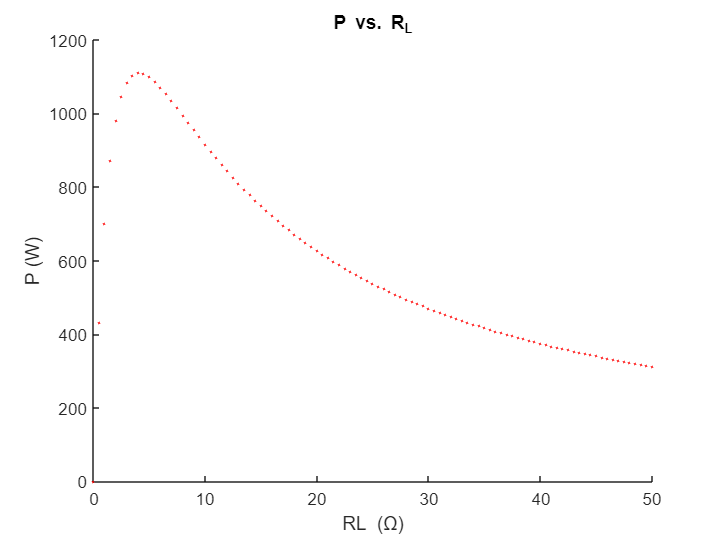

figure;  % initialize new figure

%%% enter your code below %%%
scatter(transpose(RL_values_to_try),P,1,'red')
title('P vs. R_L')
xlabel('RL  (Ω)'), ylabel('P (W)')

[P_max, index] = max(P) % find max power value from the graph and index of it in the matrix of power values

P_max = 1.1111e+03

index = 9

RL_max = RL_values_to_try(index) % find corresponding RL value that results in max power value

RL_max = 4

I3 % find corresponding current value from for loop iterating through possible RL values

I3 = 16.6667

I3^2*RL_max % check to see if current and RL values correspond to max power value

ans = 1.1111e+03

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### Final answer

Based on your plot, the maximum power dissipation of** [ >>> 1111 <<< ] **Watts occurs when $R_L$ has a resistance of **[ >>> 4 <<< ] **Ohms.

Does this power level exceed the rating of the fuse?  **[ >>> no <<< ]**